# 3 Hands-on 1

### 2.2 Signal generation and data saving

Here we can be smart and use a for loop than runs as often as we wish by just changing a single parameter.

clear all; clc;

% Some parameters to start with
fs_s = 44100;     % sampling frequency
T_s = 5;            % Duration we are looking at
f0 = 1000;      % fundamental frequency
a_k = 1;        % amplitude
t_s = 0:1/fs_s:T_s-1/fs_s;

N = 50;         % number of components

ps_1 = zeros(1,N); % in the case of zero phase
ps_2 = (pi/2)*ones(1,N);
ps_3 = 2*pi*rand(1,N);

% initialize the signal with a vector of zeros
s_1 = zeros(1,fs_s*T_s);  % Where does the fs*T come from?
s_2 = zeros(1,fs_s*T_s);
s_3 = zeros(1,fs_s*T_s);

% now the loop
for kk = 1:N
    s_1 = s_1 + a_k*sin(2*pi*kk*f0*t_s + ps_1(kk));
    s_2 = s_2 + a_k*sin(2*pi*kk*f0*t_s + ps_2(kk));
    s_3 = s_3 + a_k*sin(2*pi*kk*f0*t_s + ps_3(kk));
end

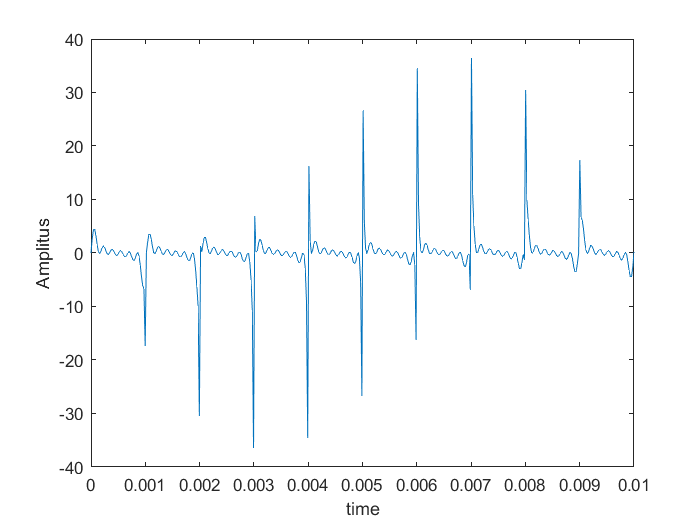

% Save the signals as .wav sound files
audiowrite('sounds/zeroPH.wav', s_1,fs_s,"BitsPerSample",32);
audiowrite('sounds/piOver2PH.wav', s_2,fs_s,"BitsPerSample",32);
audiowrite('sounds/RandPH.wav', s_3,fs_s,"BitsPerSample",32);

% plotting
figure('Name','Zero Phase')
plot(t_s,s_1)
xlabel('time')
ylabel('Amplitus')
xlim([0 .01])
saveas(gcf,'plots/ZeroPH',"png");

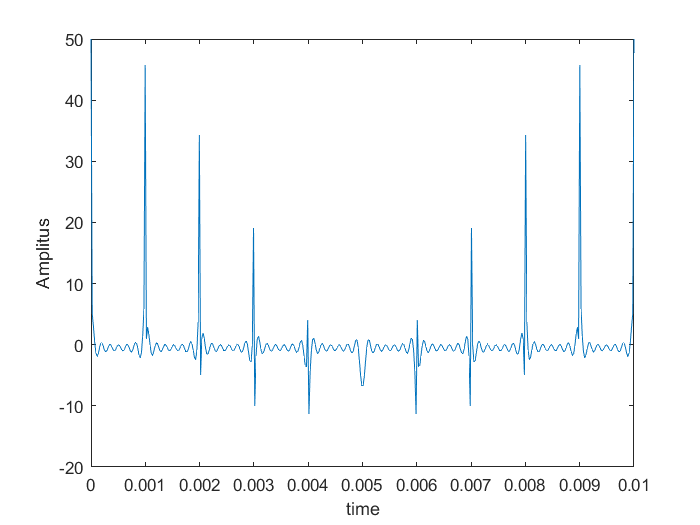

figure('Name','Pi/2 Phase')
plot(t_s,s_2)
xlabel('time')
ylabel('Amplitus')
xlim([0 .01])
saveas(gcf,'plots/PIover2PH',"png");

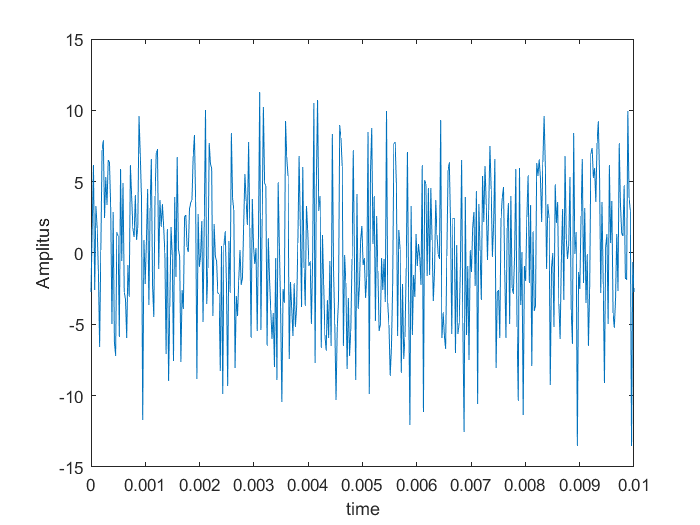

figure('Name','Random Interval Phase')
plot(t_s,s_3)
xlabel('time')
ylabel('Amplitus')
xlim([0 .01])
saveas(gcf,'plots/RandPH',"png");

soundsc(s_1);
pause(5);
soundsc(s_2);
pause(5);
soundsc(s_3); %